# Examen RA3L "intro Matlab"      20 août 2024  13h30 -> 15h00 (1h30) 

% Nom :      ADDA                                      /10
% Prénom :      SABIR
% Matricule :   

## Jauges de déformation et mesure de force

4 jauges de déformation ont été collées dans le sens de la longueur sur une latte en aluminium (2 au-dessus : $J_1$ et $J_3$ et 2 en dessous : $J_2$ et $J_4$). 

    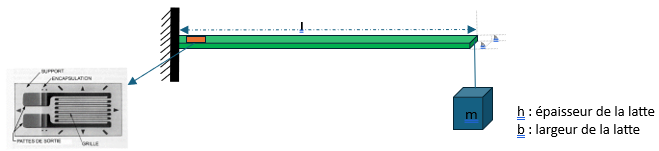

Ces jauges sont connectées électriquement en pont de Wheatstone (cf. schéma ci-dessous), alimenté avec une tension $U_S$, tandis qu'on récupère une tension $U$ sur la diagonale du pont qui varie en fonction de la masse $m$ via l'allongement des jauges $J_1$ et $J_3$ et le raccourcissement des jauges $J_2$ et $J_4$.

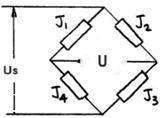

**1) Récupérer les données du fichier "Data_jauges.mat" fourni.** Ce fichier contient les vecteurs suivants :

- 'm' : masses suspendues au bout de la latte *[en kg]*.

- 'U' : tension mesurée sur la diagonale du pont *[en V]; *

- Mesures dynamiques : t *[en s]* et F *[en N]* (à utiliser à la question 4)

**Afficher les données sous forme d'un graphe présentant U en fonction de m**. 

*(1,5 points) : *

Résultat attendu :

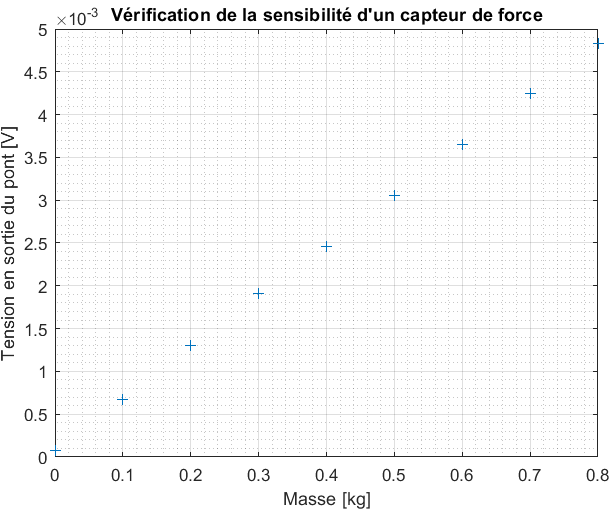

%debut
clf;
clear all ;
close all  ;
load('data_jauges.mat');

z

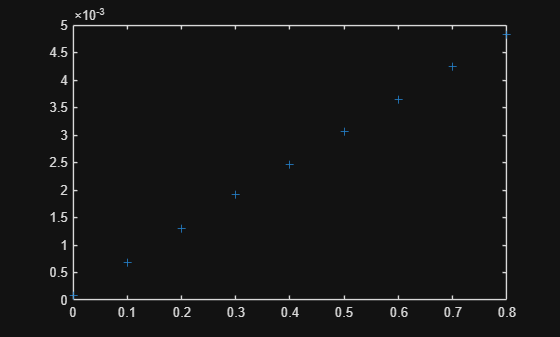

plot(m,U,'+')

2) **Déterminer l'équation de la droite qui passe le plus près des points de mesure (au sens des moindres carrés) et afficher celle-ci et son expression mathématique sur le graphe. ***(2,5 points)*

Résultat attendu :

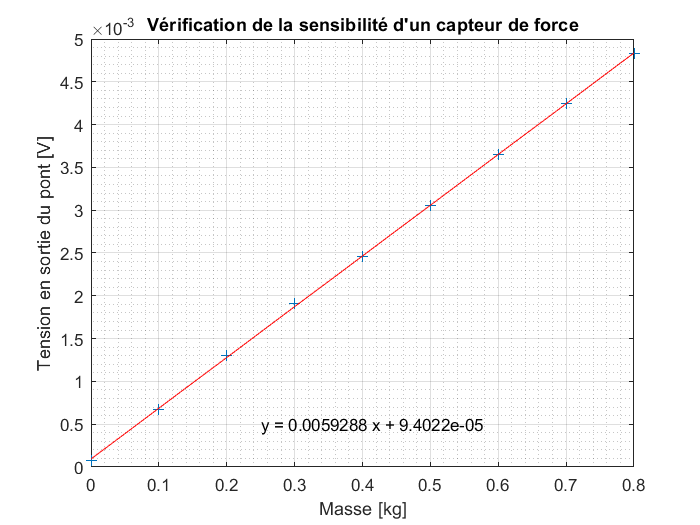

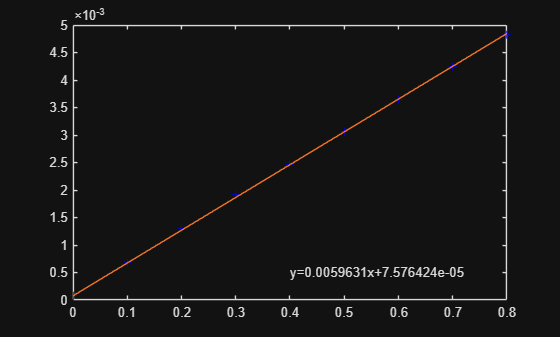

fun1=@(p,x) p(1).*x+p(2);
cost1=@(x) norm(U-fun1(x,m));
p=[0 0];
min1=fminsearch(cost1,p);

plot(m,U,'+b',m,fun1(min1,m))
text(0.4,0.5e-3,sprintf('y=%0.7fx+%5e',min1(1),min1(2)))


%equation differente de celle du prof mais alz walid tout pareil

3)** Calculer la tension théorique en sortie du montage pour les masses données plus haut via la formule suivante** :


$$U_{\textrm{th}} =2,06\ \frac{U_S \;g\;\ell \;h}{2\;E\;I}\;m$$


avec $U_S =5\;V$ $E=69\;\textrm{GPa}$, $g=9,81\;\frac{m}{s^2 }$, $\ell =0,175\;m$, $h=0,0032\;m$ et $I=69,41\;\ldotp {10}^{-12} \;m^4$

**Afficher** dans une nouvelle figure :

- Au-dessus : les points originaux, la droite ajustée et la droite théorique

- En dessous : l'écart entre les points originaux et la droite ajustée

*(1,5 points)*

Résultat attendu :

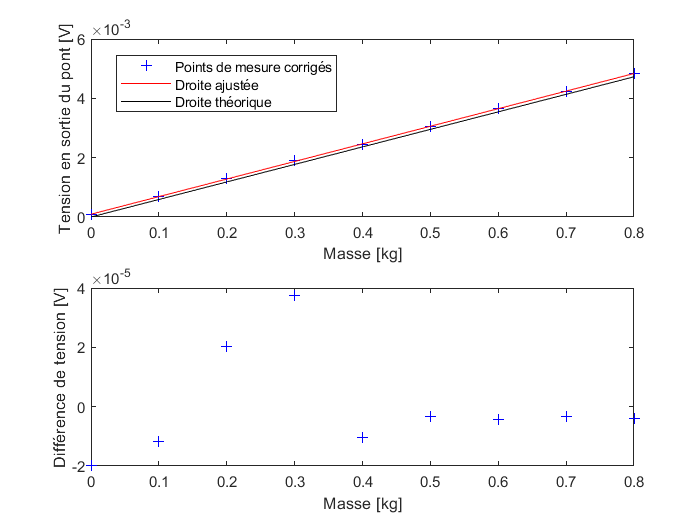

$U_{\textrm{th}} =2,06\ \frac{U_S \;g\;\ell \;h}{2\;E\;I}\;m$avec $U_S =5\;V$ $E=69\;\textrm{GPa}$, $g=9,81\;\frac{m}{s^2 }$, $\ell =0,175\;m$, $h=0,0032\;m$ et $I=69,41\;\ldotp {10}^{-12} \;m^4$

uth=2.06*5*9.81*0.175*0.0032/2/69/10^9/69.41/10^-12.*m;

uth =          0    0.0006    0.0012    0.0018    0.0024    0.0030    0.0035    0.0041    0.0047


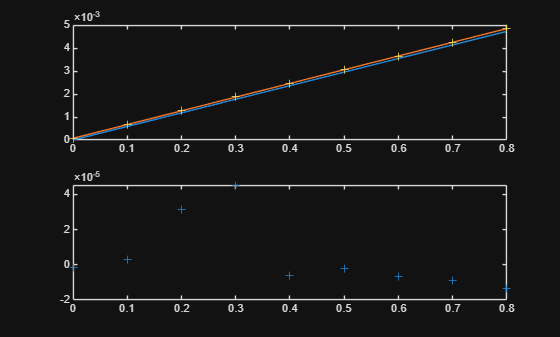

clf;
subplot(2,1,1)
plot(m,uth,m,fun1(min1,m),m,U,'+')

subplot(2,1,2)
plot(m,U-fun1(min1,m),'+')

4) **Supposons que le bout de la latte instrumentée est maintenant fixé à une table vibrante, qui lui impose une force **$F$** variable dans le temps t : **

La force est sockée dans la variable F et le temps dans la variable t du fichier "Data_jauges.mat"**. **

(a) Afficher la force $F$ en fonction du temps $t$. Vous remarquerez qu'il manque une partie des données entre 0.199 et 0.239 secondes (échantillon de temps constant). Reconstruire et afficher le signal de mesure via deux méthodes d'interpolation : "pchip" et "spline". 

(2* points*)

Résultat attendu :

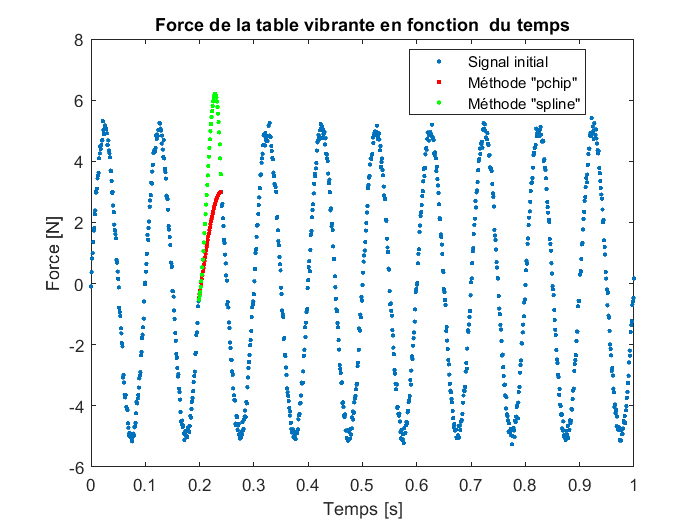

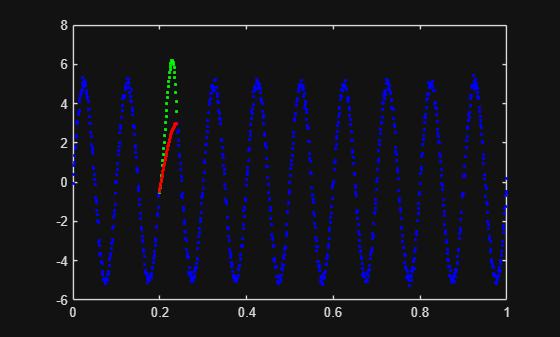

clf;
d=linspace(0.199,0.239,40);
a=interp1(t,F,d,'spline');
b=interp1(t,F,d,'pchip');


plot(t,F,'.b',d,a,'.g',d,b,'.r')

(b) Recombiner le signal original avec le signal interpolé via "spline" en deux vecteurs Fnew et tnew. (1* point*)

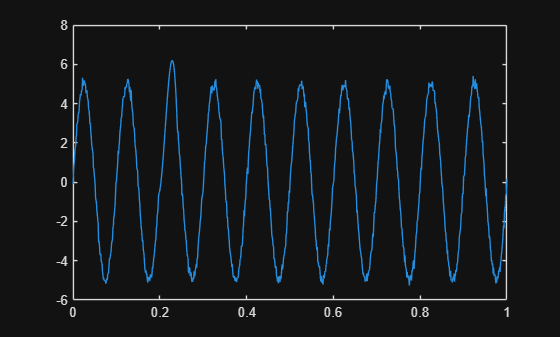

clf;
tnew=[t d];
[tnew,idx]=sort(tnew);
Fnew=[F a];
Fnew=Fnew(idx);
plot(tnew,Fnew);

(c) A partir du signal reconstruit au point (b), calculer :

- la flèche $y$ en fonction du temps $t$ via la formule ci-contre $y\left(t\right)=-\frac{F\left(t\right)\;\ell^3 }{3\;E\;I}$

- la vitesse par dérivées de la flèche du bout de la latte

(1,5* point*)

Afficher les résultats comme ci-dessous :

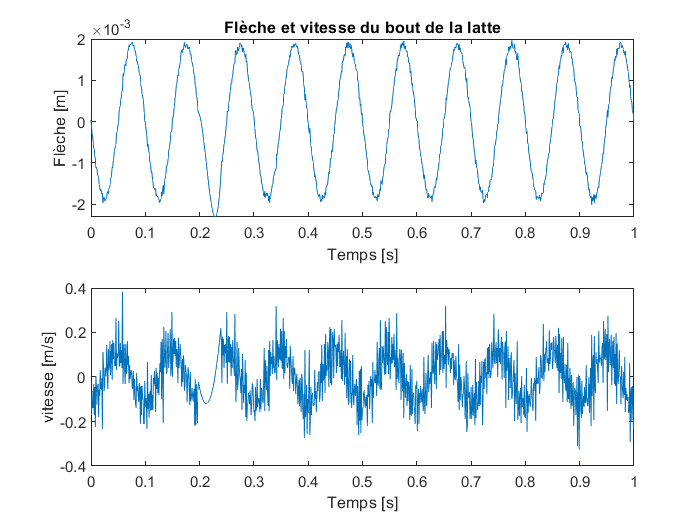

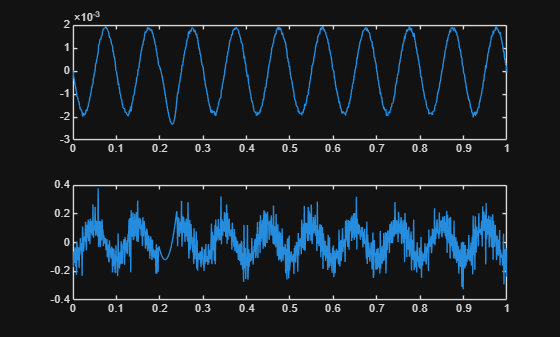

clf;
y=-Fnew.*(0.175)^3/3/69/10^9/69.41/10^-12;
v=diff(y)./diff(tnew);
subplot(2,1,1)
plot(tnew,y)

subplot(2,1,2)
plot(tnew(1:end-1),v)

© MOL L2E AIF